## Morfologia Matematica

La morfologia matematca si basa sull'interazione tra un'immagine e una piccola forma chiamata **Elemento Strutturante (SE)**. L'SE agisce come una "sonda" che scivola sull'immagine per modificarla

**Regola IMPORTANTE**: Per convenzione, le operazioni morfologiche lavorano su **oggetti chiari su sfondo scuro**. Se si ha il contrario, basta invertire l'immagine.

### Creare un Elemento Strutturante (SE)

L'SE è una piccola matrice binaria che definisce la forma della nostra "sonda".

In matlab possiamo crearli facilmente con la funzione strel

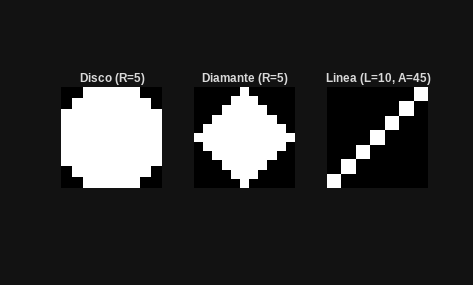

% SE a forma di disco, raggio 5 pixel
se_disco = strel("disk",5);

% Se a forma di diamante
se_diamante = strel("diamond",5);

% Se a forma di linea, lunghezza 10 pixel, angolo 45°
se_linea = strel("line", 10, 45);

subplot(1, 3, 1); imshow(se_disco.Neighborhood); title('Disco (R=5)');
subplot(1, 3, 2); imshow(se_diamante.Neighborhood); title('Diamante (R=5)');
subplot(1, 3, 3); imshow(se_linea.Neighborhood); title('Linea (L=10, A=45)');

### Gli Operatori di Base - Erosione e Dilatazione

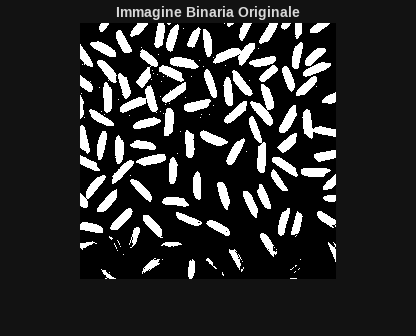

img_binaria = imread("rice.png");
img_binaria = imbinarize(img_binaria);
figure; imshow(img_binaria); title('Immagine Binaria Originale');

### Erosione

L'erosione **restringe** o **assottiglia** gli oggetti chiari. Rimuove i pixel dai bordi degli oggetti. Un oggetto più piccolo dell'elemento strutturante verrà completamente eliminato.

**Concetto**: Un pixel rimane bianco solo se l'intero elemento strutturante non entra in contatto con un valore 0 dell'immagine (min). Il valore del pixel nell'immagine elaborata è il **minimo** dei valori coperti dall'elemento strutturante.

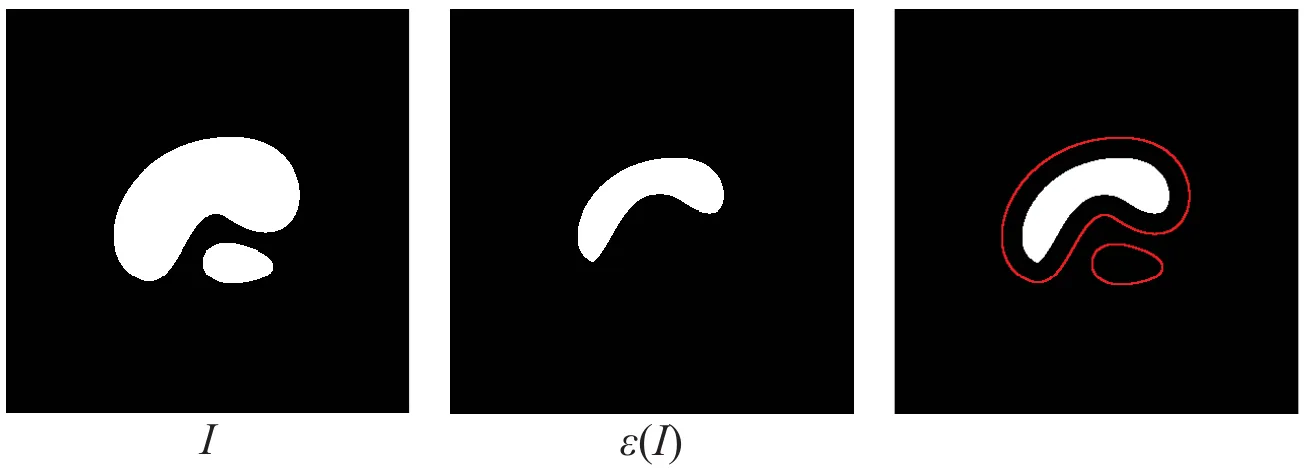

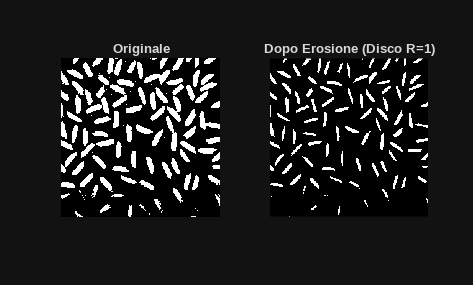

% usiamo un SE piccolo per un effetto leggero
se = strel("disk",2);

% Applichiamo l'erosione
img_erosa = imerode(img_binaria,se);

figure('Name', 'Erosione');
subplot(1, 2, 1); imshow(img_binaria); title('Originale');
subplot(1, 2, 2); imshow(img_erosa); title('Dopo Erosione (Disco R=1)');

### Dilatazione

La dilatazione **espande** o **inspessisce** gli oggetti chiari. Aggiunge pixel ai bordi degli oggetti, riempiendo piccoli buchi o collegando parti vicine.

**Concetto**: Un pixel diventa bianco se anche solo una parte dell'elemento strutturante, centrato su quel pixel, tocca un pixel bianco dell'immagine (max). Il valore del pixel nell'immagine elaborata è il **massimo** dei valori coperti dall'elemento strutturante. 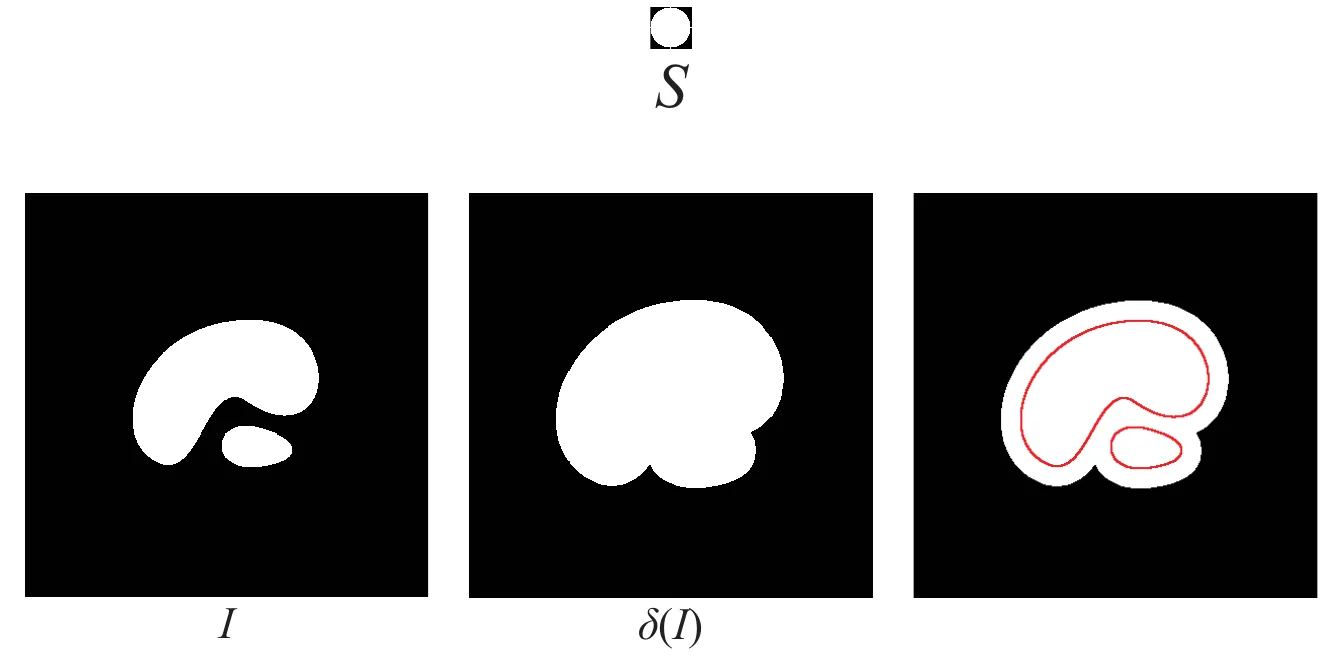

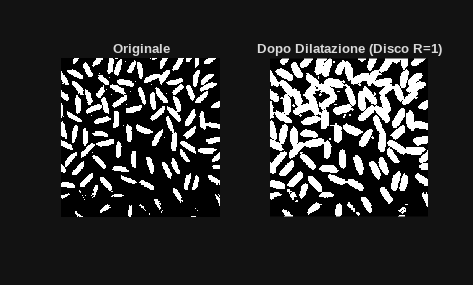

% usiamo il SE precedente
% Applichiamo la dilatazione
img_dilatata = imdilate(img_binaria,se);
figure('Name', 'Dilatazione');
subplot(1, 2, 1); imshow(img_binaria); title('Originale');
subplot(1, 2, 2); imshow(img_dilatata); title('Dopo Dilatazione (Disco R=1)');

## Operatori Composti

### Apertura

L'apertura è un **EROSIONE seguita da una DILATAZIONE** con lo stesso elemento strutturante. 

Rimuove piccoli oggetti e dettagli sottili, senza però alterare la dimensione generale degli oggetti più grandi. E come levigare i contorni dall'interno.

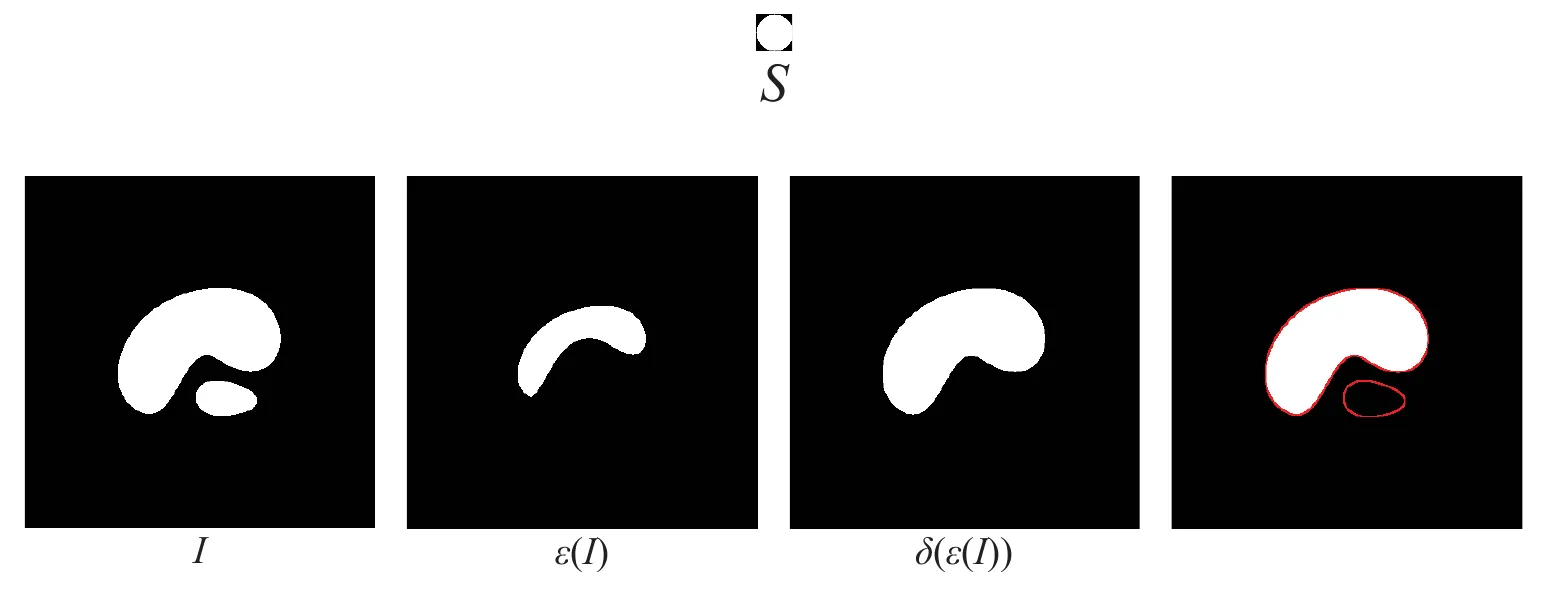

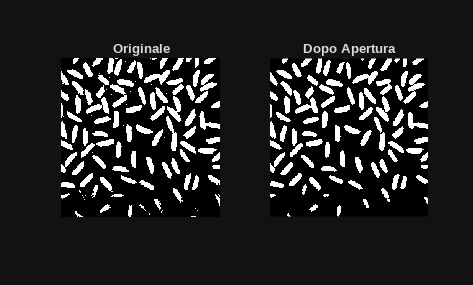

% Applichiamo l'apertura
img_aperta = imopen(img_binaria,se);

figure('Name', 'Apertura');
subplot(1, 2, 1); imshow(img_binaria); title('Originale');
subplot(1, 2, 2); imshow(img_aperta); title('Dopo Apertura');

### Chiusura

La chiusura è una **DILATAZIONE seguita da un'EROSIONE **con lo stesso elemento strutturante.

Riempie piccoli buchi all'interno degli oggetti e collega piccole interruzioni, senza alterare la dimensione generale.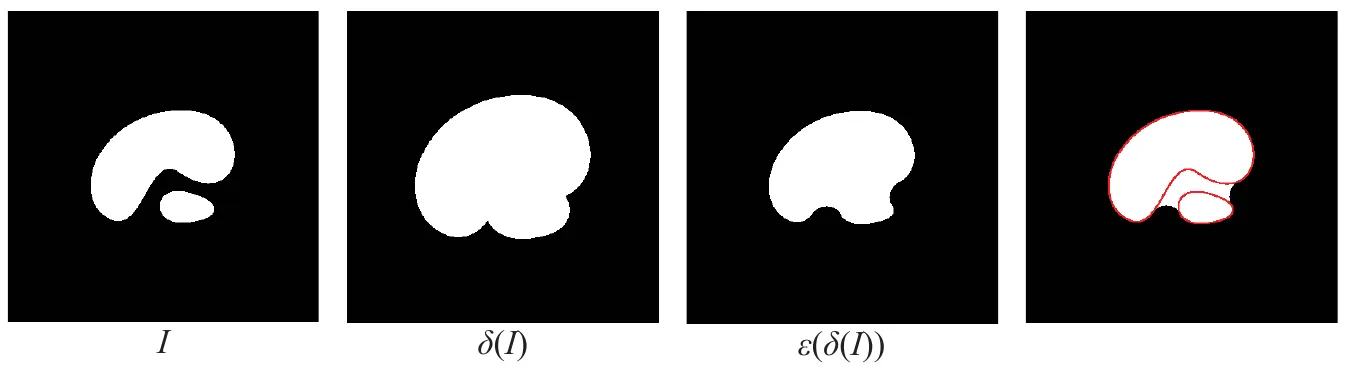

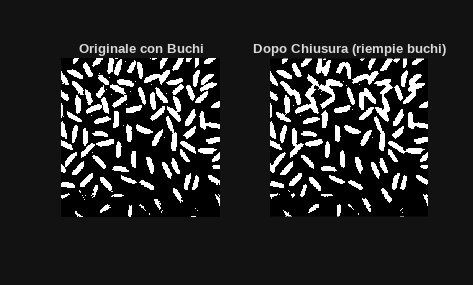

img_chiusa = imclose(img_binaria,se);

figure('Name', 'Chiusura');
subplot(1, 2, 1); imshow(img_binaria); title('Originale con Buchi');
subplot(1, 2, 2); imshow(img_chiusa); title('Dopo Chiusura (riempie buchi)');

## Altre Applicazioni

### Gradiente Morfologico (rho)

Il gradiente morfologico è la **differenza tra l'immagine dilatata e l'immagine erosa. Produce un contorno degli oggetti.**

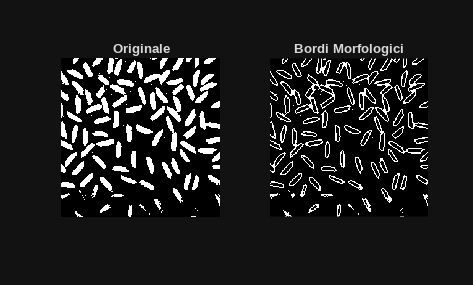

img_gradiente = img_chiusa - img_erosa;

figure('Name', 'Gradiente Morfologico');
subplot(1, 2, 1); imshow(img_binaria); title('Originale');
subplot(1, 2, 2); imshow(img_gradiente); title('Bordi Morfologici');

### Top-Hat e Bottom-Hat

- **Top-Hat** : È la **differenza tra l'immagine originale e la sua apertura. Evidenzia i piccoli dettagli chiari che l'apertura ha rimosso. **

- **Bottom-Hat:** È la **differeza tra la chiusura dell'immagine e l'originale**. Evidenzia i piccoli dettagli scuri.

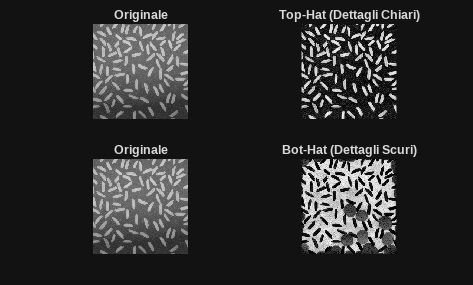

% Usiamo un'immagine in scala di grigi con dettagli
img_grigi = imread('rice.png');

% Usiamo un SE grande per trovare lo sfondo (illuminazione non uniforme)
se_grande = strel('disk', 15);

% Top-hat trova gli oggetti (riso) più chiari dello sfondo
img_tophat = imtophat(img_grigi, se_grande);

% Bottom-hat troverebbe dettagli scuri (qui non ce ne sono)
img_bothat = imbothat(img_grigi, se_grande);

figure;
subplot(2, 2, 1); imshow(img_grigi); title('Originale');
subplot(2, 2, 2); imshow(img_tophat, []); title('Top-Hat (Dettagli Chiari)');
subplot(2, 2, 3); imshow(img_grigi); title('Originale');
subplot(2, 2, 4); imshow(img_bothat, []); title('Bot-Hat (Dettagli Scuri)');